## Adaptation du réseau neuronal 

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


lay = net.Layers

lay =   144x1 Layer array with layers:

     1   'data'                           Image Input                   224x224x3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7x7x3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1x1x64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

Facultatif : permet de voir les propriétés de la couche d'entrée (taille d'image)

inLayer = lay(1)

inLayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inSize = inLayer.InputSize

inSize =    224   224     3


Création du nouveau réseau en remplaçant deux couches par des couches vierges

lgraph = layerGraph(net);
newFc = fullyConnectedLayer(2,"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out");
lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Images d'entraînement et test : les datastores

imds = imageDatastore("grape2classes/", "IncludeSubfolders",true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../0075b632-2e34-4e4f-9697-fe2b332b7ef8___FAM_B.Msls 4399_flipLR.JPG';
                              ' .../01162551-b800-4df8-ac46-64d17d6ac5bf___FAM_B.Msls 1153_flipLR.JPG';
                              ' .../011f307f-e06b-4604-9419-d940f7b00290___FAM_B.Msls 1096.JPG'
                               ... and 889 more
                              }
                      Labels: [Grape___Esca; Grape___Esca; Grape___Esca ... and 889 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


imds.Labels

ans = 892×1 categorical array
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 


Répartition aléatoire des images, 

70% pour le training / 30% pour le test

[trainAllImgs, testAllImgs] = splitEachLabel(imds, 0.7, "randomized")

trainAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' .../011f307f-e06b-4604-9419-d940f7b00290___FAM_B.Msls 1096.JPG';
                              ' .../02223cc6-30d2-408d-a091-65257d044a50___FAM_B.Msls 0908_flipLR.JPG';
                              ' .../023df989-ab4c-4f66-a6c8-a41c1142ab7d___FAM_B.Msls 1834_flipLR.JPG'
                               ... and 621 more
                              }
                      Labels: [Grape___Esca; Grape___Esca; Grape___Esca ... and 621 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


testAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' .../0075b632-2e34-4e4f-9697-fe2b332b7ef8___FAM_B.Msls 4399_flipLR.JPG';
                              ' .../01162551-b800-4df8-ac46-64d17d6ac5bf___FAM_B.Msls 1153_flipLR.JPG';
                              ' .../01c74b8d-1113-47c0-86a3-6ceea27853c0___FAM_B.Msls 4113.JPG'
                               ... and 265 more
                              }
                      Labels: [Grape___Esca; Grape___Esca; Grape___Esca ... and 265 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


AugmentedImageDatastore : permet d'ajouter un traitement automatisé à la volée sans modifier l'image originale

Ici on adapte la taille de l'image à la taille d'entrée du réseau sans changer

trainds = augmentedImageDatastore([224 224],trainAllImgs);
testds = augmentedImageDatastore([224 224],testAllImgs);

## Entraînement du réseau

trainds = 624 images divisible par 52 (20) et 78 (8) --> mini-batch de 78 images

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:30 |       60.26% |       0.9724 |          0.0010 |


|       3 |          24 |       00:11:09 |      100.00% |       0.0021 |          0.0010 |
|========================================================================================|


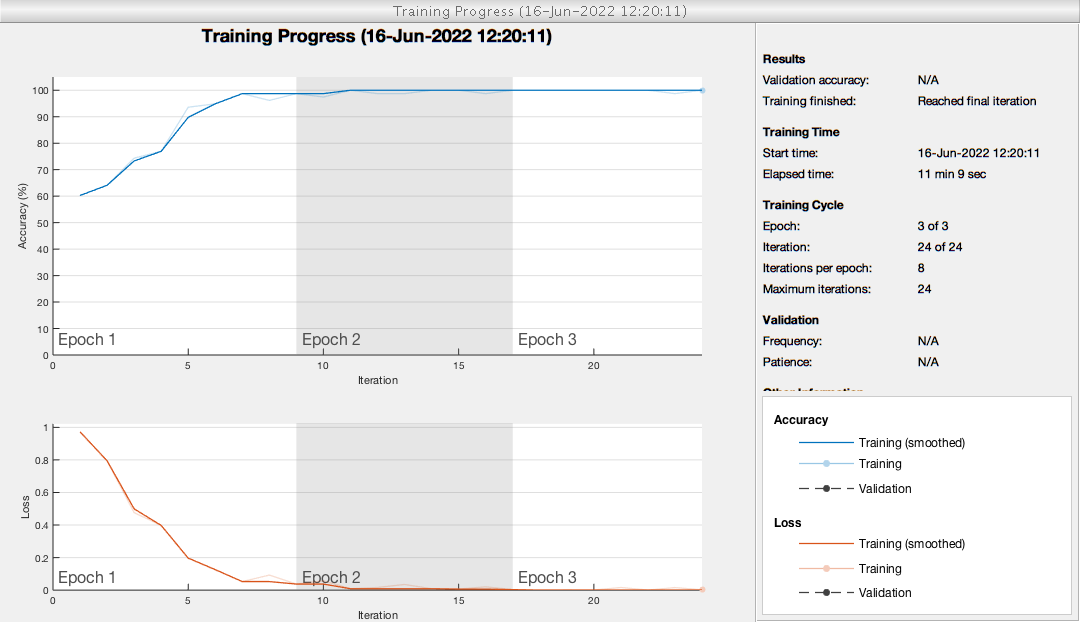

vignenette =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


options = trainingOptions("sgdm",...
    'InitialLearnRate', 0.001, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',3, ...
    'MiniBatchSize',78, ...
    'Plots','training-progress',...
    'Shuffle','every-epoch');
    
vignenette = trainNetwork(trainds,lgraph,options)

save VigneNette

## Evaluation du réseau sur les données de test

predictions = classify(vignenette,testds)

predictions = 268×1 categorical array
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 


testAllImgs.Labels

ans = 268×1 categorical array
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 
     Grape___Esca 


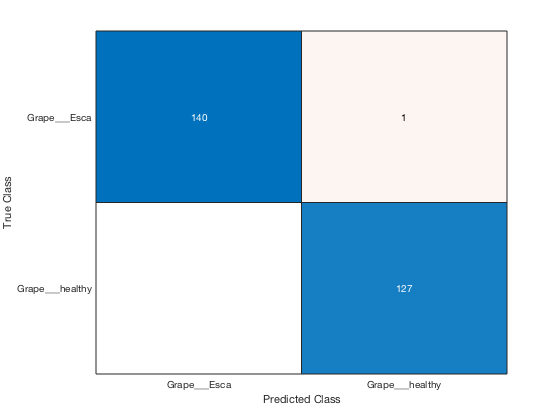

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


confusionchart(testAllImgs.Labels, predictions)

## Temps d'exécution sur une image

load VigneNette.mat
net = vignenette

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


img = imread("grape.jpg" );
img = imresize(img, [224,224]);
tic
label = classify (vignenette,img)

label = categorical
     Grape___healthy 


toc

Elapsed time is 0.736453 seconds.



img = imread("grapeBlackRot.jpg" );
img = imresize(img, [224,224]);
tic
label = classify (vignenette,img)

label = categorical
     Grape___Esca 


toc

Elapsed time is 0.162036 seconds.
